# **LAB: **CWRU Bearing Fault Diagnosis

**Name: Kim Inyeop  **

### Drive End Bearing Experiment

## 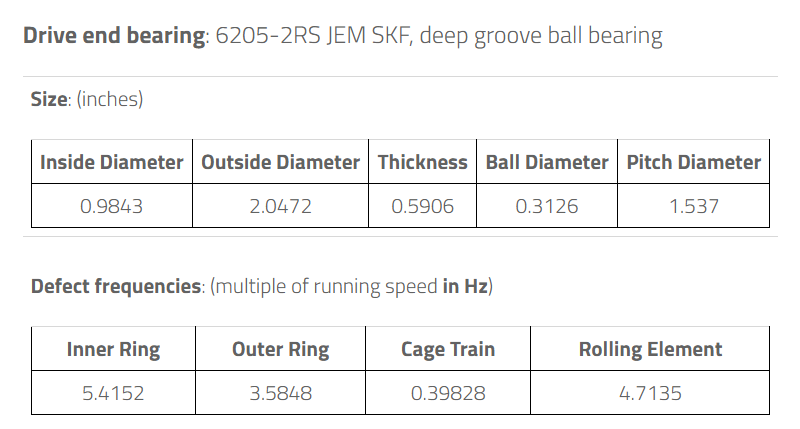

## Load Dataset

close all
clear
load('inner_007_1hp.mat')
load('normal_1hp.mat')
load('outer_007_1hp.mat')



## **Preprocessing**

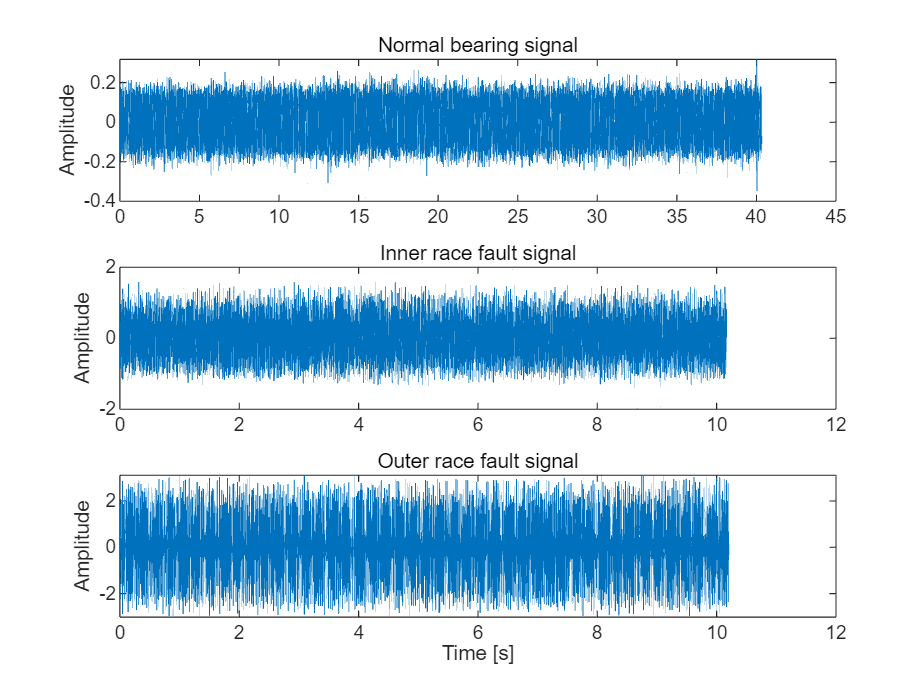

x_normal = X098_DE_time;   % Normal
x_inner  = X106_DE_time;   % Inner fault
x_outer  = X131_DE_time;   % Outer fault

fs = 12000;                % Sampling frequency [Hz]
t_normal = (0:length(x_normal)-1)/fs;
t_inner  = (0:length(x_inner)-1)/fs;
t_outer  = (0:length(x_outer)-1)/fs;

% === Plot ===
figure;
subplot(3,1,1)
plot(t_normal, x_normal); title('Normal bearing signal'); ylabel('Amplitude');
subplot(3,1,2)
plot(t_inner, x_inner); title('Inner race fault signal'); ylabel('Amplitude');
subplot(3,1,3)
plot(t_outer, x_outer); title('Outer race fault signal'); ylabel('Amplitude');
xlabel('Time [s]');

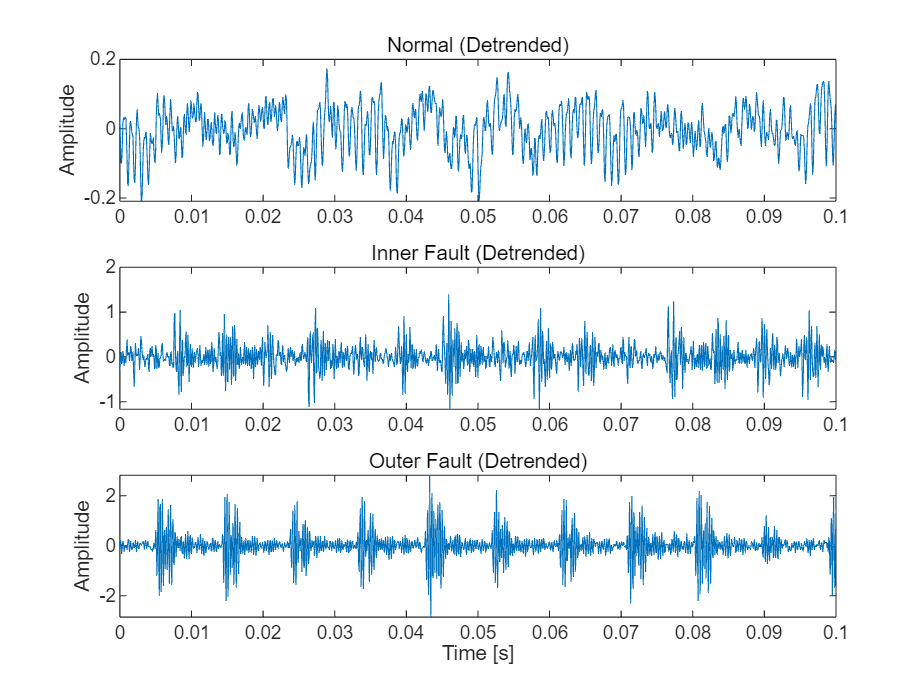

%% Step 2. Preprocessing: Detrend

% --- Detrend (offset 제거)
x_normal_dt = detrend(x_normal);
x_inner_dt  = detrend(x_inner);
x_outer_dt  = detrend(x_outer);

% --- 시각화 비교
figure;
subplot(3,1,1); 
plot(t_normal, x_normal_dt);
xlim([0 0.1]);
title('Normal (Detrended)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t_inner, x_inner_dt);
xlim([0 0.1]); 
title('Inner Fault (Detrended)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t_outer, x_outer_dt);
xlim([0 0.1]); 
title('Outer Fault (Detrended)');
xlabel('Time [s]');
ylabel('Amplitude');

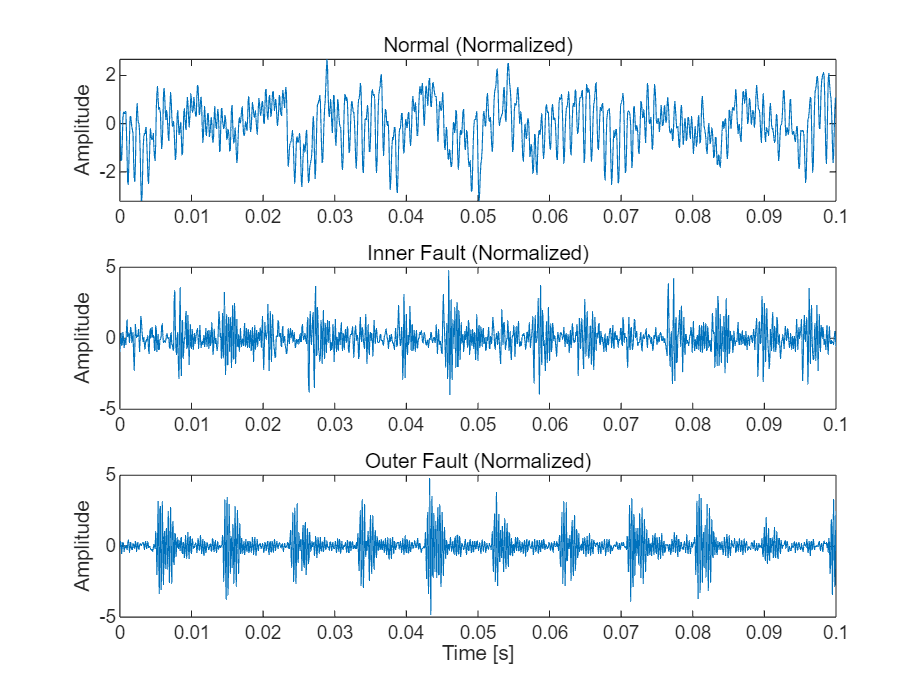

%% Step 3. Preprocessing: Normalization (Z-score)

% --- Z-score normalization
x_normal_norm = (x_normal_dt - mean(x_normal_dt)) / std(x_normal_dt);
x_inner_norm  = (x_inner_dt  - mean(x_inner_dt))  / std(x_inner_dt);
x_outer_norm  = (x_outer_dt  - mean(x_outer_dt))  / std(x_outer_dt);

% --- 시각화 비교
figure;
subplot(3,1,1);
plot(t_normal, x_normal_norm);
xlim([0 0.1]); 
title('Normal (Normalized)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t_inner, x_inner_norm);
xlim([0 0.1]); 
title('Inner Fault (Normalized)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t_outer, x_outer_norm);
xlim([0 0.1]); 
title('Outer Fault (Normalized)');
xlabel('Time [s]');
ylabel('Amplitude');

## **Features Extraction**

• Extract Time-Domain Features

- Mean, Std, Skewness, Kurtosis, Peak2Peak, RMS, CrestFactor,  ShapeFactor, ImpulseFactor, MarginFactor, Energy etc

• Extract Frequency-Domain Features

-   Basic features,  SKMean, SKStd, SKSkewness, SKKurtosis, etc

• Envelop Extraction

• Plot  STFT 

• Plot  Kurtogram

• Analyze Spectral Kurtosis

%% Step 1. Time-Domain Feature Extraction (fixed table version)

% --- Feature 계산 함수
calc_features = @(x) struct( ...
    'Mean', mean(x), ...
    'Std', std(x), ...
    'Skewness', skewness(x), ...
    'Kurtosis', kurtosis(x), ...
    'Peak2Peak', peak2peak(x), ...
    'RMS', rms(x), ...
    'CrestFactor', max(abs(x)) / rms(x), ...
    'ShapeFactor', rms(x) / mean(abs(x)), ...
    'ImpulseFactor', max(abs(x)) / mean(abs(x)), ...
    'MarginFactor', max(abs(x)) / (mean(sqrt(abs(x)))^2), ...
    'Energy', sum(x.^2) ...
);

% --- 각 신호에 대해 계산
feat_normal = calc_features(x_normal_norm);
feat_inner  = calc_features(x_inner_norm);
feat_outer  = calc_features(x_outer_norm);

% --- 구조체를 table로 변환 (열 방향으로)
features = fieldnames(feat_normal);
normal_vals = struct2array(feat_normal)';
inner_vals  = struct2array(feat_inner)';
outer_vals  = struct2array(feat_outer)';

% --- 테이블로 정리
T = table(features, normal_vals, inner_vals, outer_vals, ...
    'VariableNames', {'Feature','Normal','Inner','Outer'});

disp(T)

         Feature           Normal         Inner          Outer   
    _________________    ___________    __________    ___________

    {'Mean'         }    -2.4903e-17    1.0382e-17    -6.4713e-18
    {'Std'          }              1             1              1
    {'Skewness'     }       -0.17306       0.13044       0.033408
    {'Kurtosis'     }         2.9306        5.5422          7.595
    {'Peak2Peak'    }         10.184        10.187         10.344
    {'RMS'          }              1             1              1
    {'CrestFactor'  }         5.5285        5.3773         5.2503
    {'ShapeFactor'  }         1.2493        1.4098         1.6152
    {'ImpulseFactor'}         6.9067        7.5807         8.4801
    {'MarginFactor' }         8.1401        9.5427          11.67
    {'Energy'       }      4.839e+05    1.2199e+05     1.2243e+05



%% Step. Frequency-Domain Feature Extraction
fs = 12000;

% --- FFT 수행
N = length(x_inner_norm);
f = (0:N/2-1)*(fs/N);
X_normal = abs(fft(x_normal_norm));
X_inner  = abs(fft(x_inner_norm));
X_outer  = abs(fft(x_outer_norm));

% --- 양쪽 스펙트럼 중 절반만 사용
X_normal = X_normal(1:floor(N/2))

X_normal = 1.0e+05 *

    0.0000
    0.0217
    0.0440
    0.0660
    0.0301
    0.0387
    0.0116
    0.0054
    0.0376
    0.0041


X_inner  = X_inner(1:floor(N/2));
X_outer  = X_outer(1:floor(N/2));

% --- Helper function: Spectral features 계산
calc_spec_features = @(X) struct( ...
    'SKMean', mean(X), ...
    'SKStd', std(X), ...
    'SKSkewness', skewness(X), ...
    'SKKurtosis', kurtosis(X), ...
    'SpecEnergy', sum(X.^2), ...
    'SpecEntropy', -sum((X/sum(X)) .* log(X/sum(X) + eps)) ...
);

featF_normal = calc_spec_features(X_normal);
featF_inner  = calc_spec_features(X_inner);
featF_outer  = calc_spec_features(X_outer);

% --- 테이블로 정리
features = fieldnames(featF_normal);
vals_normal = struct2array(featF_normal)';
vals_inner  = struct2array(featF_inner)';
vals_outer  = struct2array(featF_outer)';

T_freq = table(features, vals_normal, vals_inner, vals_outer, ...
    'VariableNames', {'Feature','Normal','Inner','Outer'});

disp(T_freq)

        Feature          Normal        Inner         Outer  
    _______________    __________    __________    _________

    {'SKMean'     }        459.21        106.49       86.816
    {'SKStd'      }          1198        332.65        339.6
    {'SKSkewness' }        45.311        20.052       15.889
    {'SKKurtosis' }        3223.4        668.16       414.27
    {'SpecEnergy' }    1.0039e+11    7.4408e+09    7.494e+09
    {'SpecEntropy'}        10.396        9.8866       9.4146



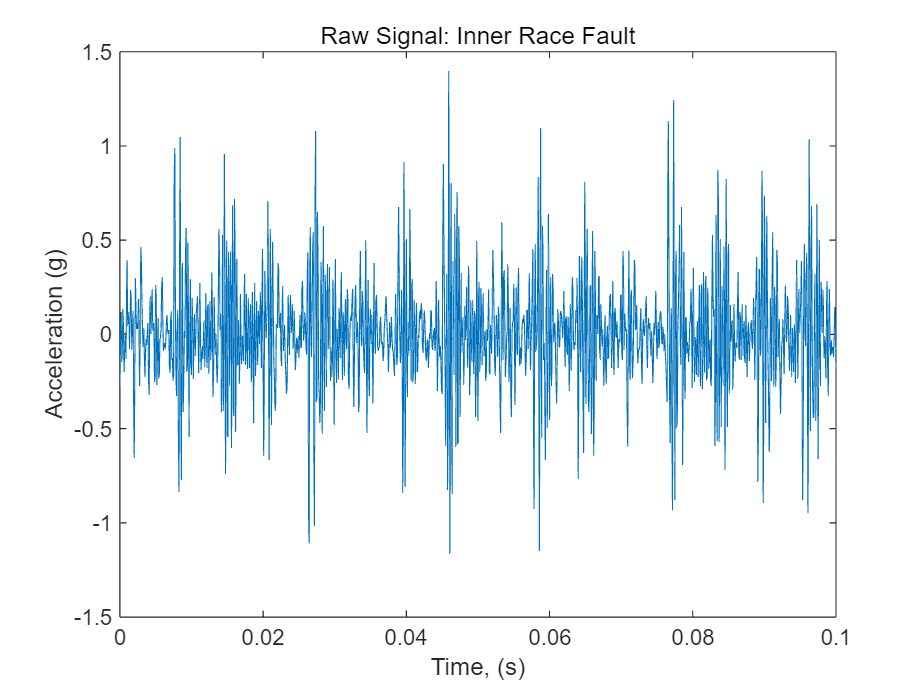

figure
plot(t_inner, x_inner)
xlabel('Time, (s)')
ylabel('Acceleration (g)')
title('Raw Signal: Inner Race Fault')
xlim([0 0.1])

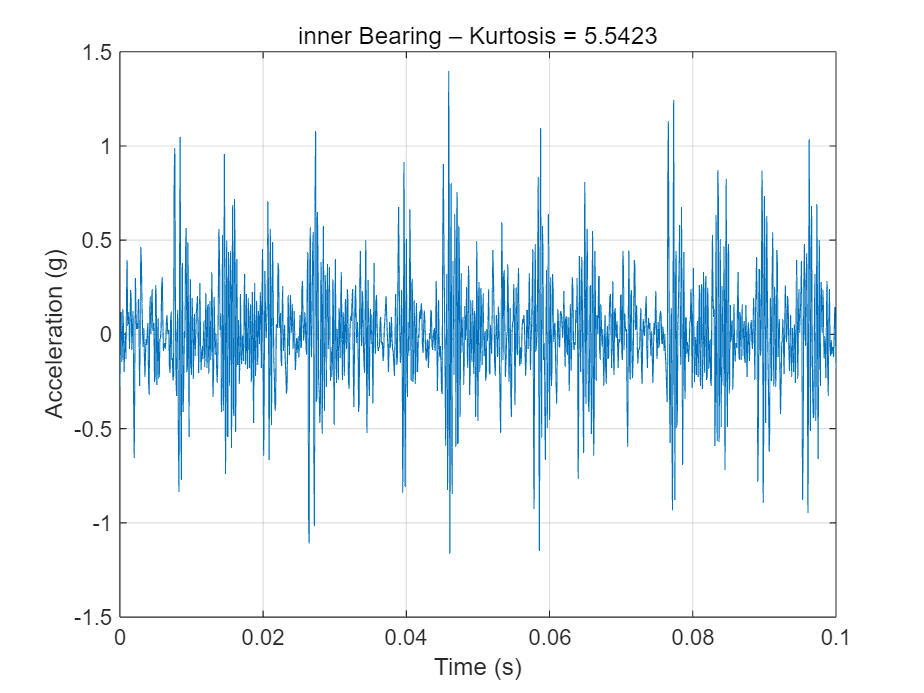

%% ================================
% STEP 2 — Kurtosis (Normal)
%% ================================

% Kurtosis 계산
kurt_inner = kurtosis(x_inner);

% Plot
figure;
plot(t_inner, x_inner);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title(['inner Bearing – Kurtosis = ' num2str(kurt_inner,'%.4f')]);
xlim([0 0.1]);
grid on;

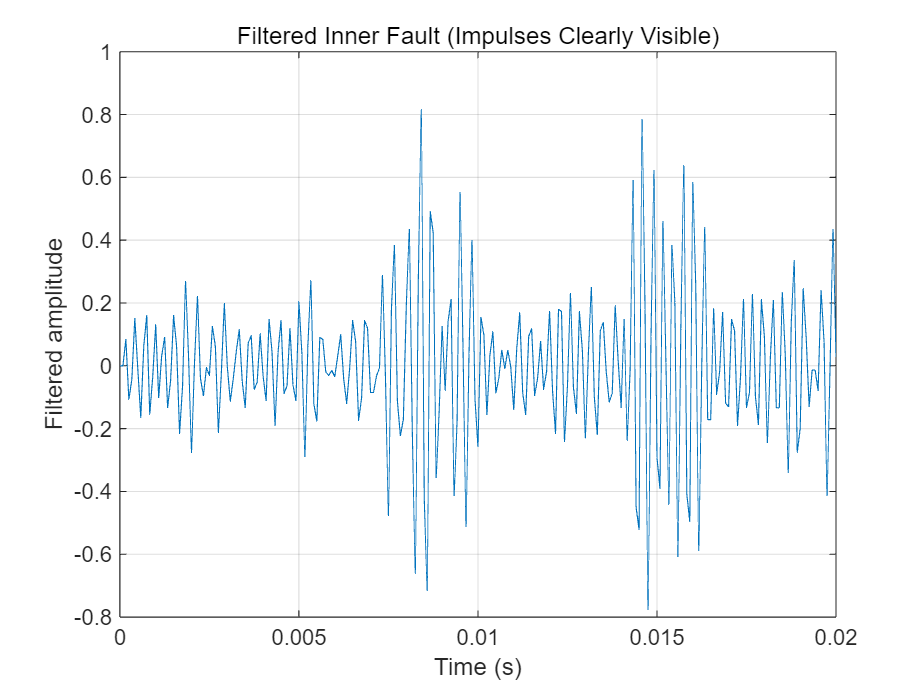

bpFilt = designfilt('bandpassfir',...
    'FilterOrder', 800, ...
    'CutoffFrequency1', 2500, ...
    'CutoffFrequency2', 5000, ...
    'SampleRate', fs);

x_inner_filt = filtfilt(bpFilt, x_inner);

idx = t_inner <= 0.02;
figure;
plot(t_inner(idx), x_inner_filt(idx));
xlabel('Time (s)'); ylabel('Filtered amplitude');
title('Filtered Inner Fault (Impulses Clearly Visible)');

grid on;

analytic = hilbert(x_inner_filt);
env = abs(analytic);
ENV_FFT = abs(fft(env));
L = length(env);
f = (0:L-1)*(fs/L);


rpm = X106RPM;      % 네 파일 안에 있는 RPM 값
fr  = rpm / 60;     % 반드시 이 라인이 먼저 있어야 함

BPFI = 5.4152 * fr;
BPFO = 3.5848 * fr;
BSF  = 4.7135 * fr;
FTF  = 0.39828 * fr;


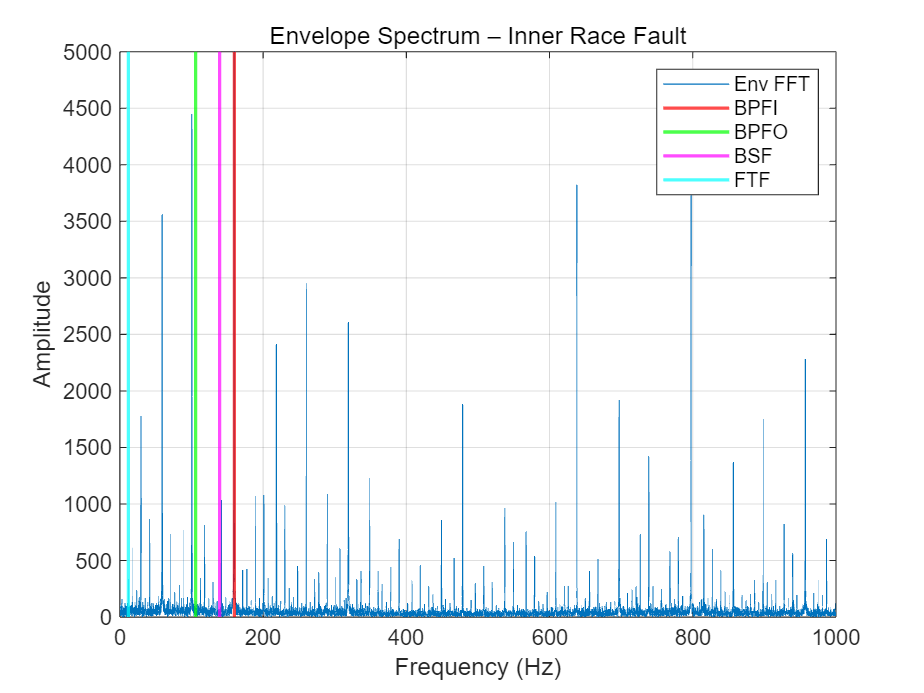

%% === Plot Envelope Spectrum ===
figure;
halfL = floor(L/2);
plot(f(1:halfL), ENV_FFT(1:halfL)); hold on;

title('Envelope Spectrum – Inner Race Fault');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;
xlim([0 1000]);
ylim([0 5000]);

% === Mark fault frequencies ===
xline(BPFI,'r','LineWidth',1.5);
xline(BPFO,'g','LineWidth',1.5);
xline(BSF ,'m','LineWidth',1.5);
xline(FTF ,'c','LineWidth',1.5);

legend('Env FFT','BPFI','BPFO','BSF','FTF');

%% === Filtered inner signal plotting ===
bpFilt = designfilt('bandpassfir',...
    'FilterOrder', 800, ...
    'CutoffFrequency1', 2500, ...
    'CutoffFrequency2', 5000, ...
    'SampleRate', fs);

x_inner_filt = filtfilt(bpFilt, x_inner);

idx = t_inner <= 0.02

idx = 1×121991 logical 배열
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


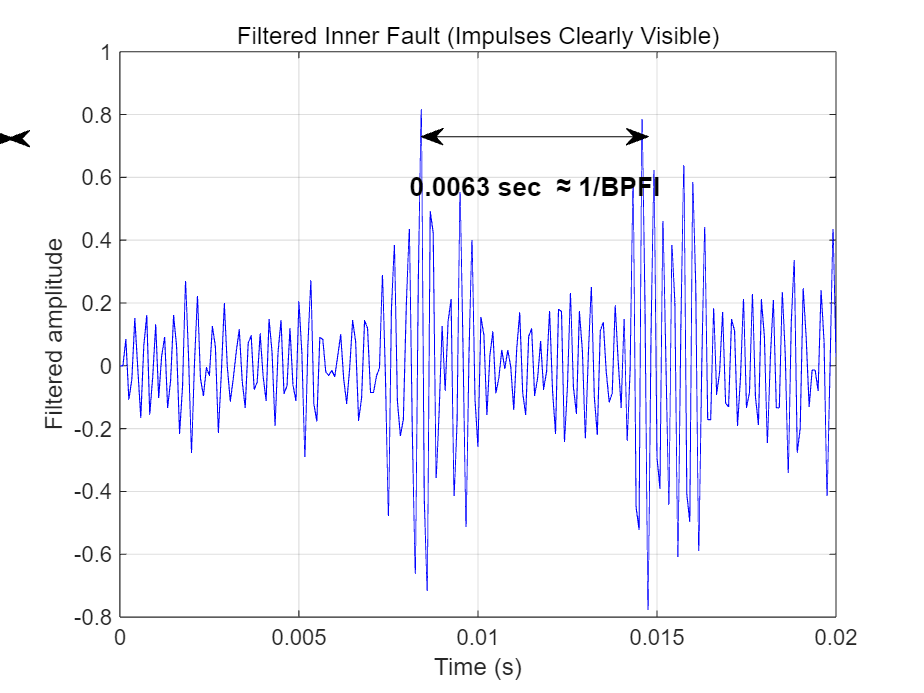


figure;
plot(t_inner(idx), x_inner_filt(idx), 'b');
xlabel('Time (s)');
ylabel('Filtered amplitude');
title('Filtered Inner Fault (Impulses Clearly Visible)');
grid on;
hold on;

%% === Mark two impulse peaks manually or automatically ===
% 예: 두 충격 사이 시간 (직접 넘어온 값이거나 자동으로 찾은 값)
t1 = 0.00841;  
t2 = 0.01475;

% 화살표 넣기 (양쪽 화살표)
annotation('doublearrow',...
    [t1 t2], [0.8 0.8]);  
% x축 비율을 normalized coords로 바꿔야 하므로 아래 조정 필요

% -----------------------
% 정확한 annotation 위치 계산
% -----------------------
ax = gca;
ax_pos = ax.Position;

x_limits = ax.XLim;
y_limits = ax.YLim;

% normalize to figure coordinates
x1_norm = ax_pos(1) + (t1 - x_limits(1)) / diff(x_limits) * ax_pos(3);
x2_norm = ax_pos(1) + (t2 - x_limits(1)) / diff(x_limits) * ax_pos(3);
y_norm  = ax_pos(2) + 0.85 * ax_pos(4);

annotation('doublearrow', [x1_norm x2_norm], [y_norm y_norm]);

%% === Add text showing delta T ===
T = t2 - t1;
mid = (t1 + t2) / 2;

text(mid, max(x_inner_filt(idx))*0.7, ...
    sprintf('%.4f sec  ≈ 1/BPFI', T), ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 12, 'FontWeight', 'bold');

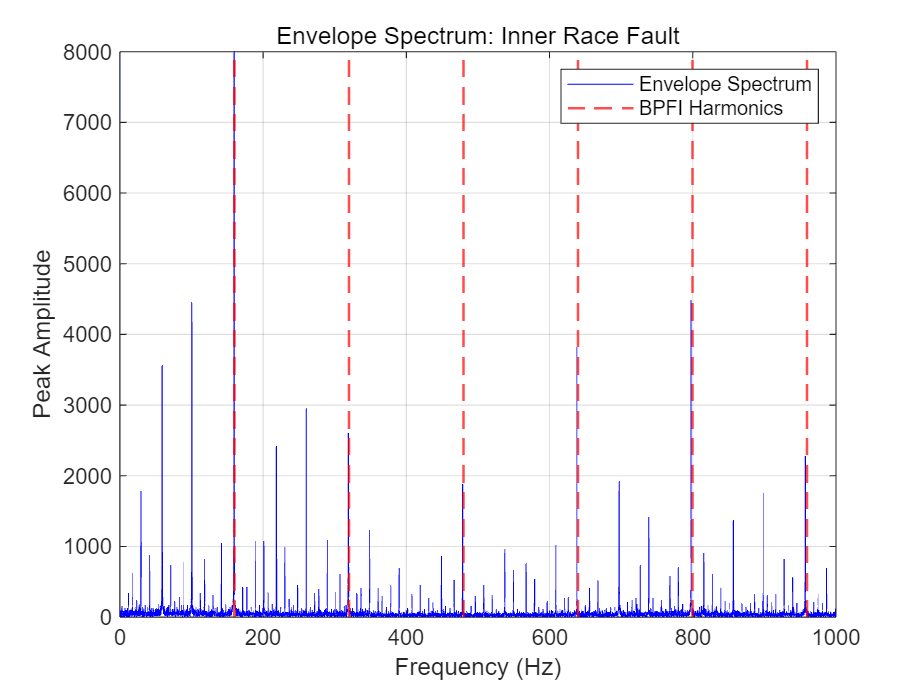

%% === 1. Envelope Spectrum 준비 ===
ENV_FFT = abs(fft(env));      % 이미 계산됨
L = length(env);
f  = (0:L-1)*(fs/L);
halfL = floor(L/2);

% Plot
figure;
plot(f(1:halfL), ENV_FFT(1:halfL), 'b'); hold on;
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Inner Race Fault');
ylim([0 8000]);
grid on;


%% === 2. BPFI Harmonics 표시 ===
ncomb = 10;               % 표시할 고조파 개수
fundamental = BPFI;       % 너의 계산된 BPFI 값 사용

for k = 1:ncomb
    harmonic_freq = k * fundamental;

    if harmonic_freq < 1000     % xlim 안에 있을 때만 표시
        xline(harmonic_freq,'r--','LineWidth',1.2);
        text(harmonic_freq, max(ENV_FFT(1:halfL))*0.8,...
            sprintf('%d×BPFI', k), ...
            'HorizontalAlignment','center',...
            'Rotation',90, 'FontSize',8, 'Color','r');
    end
end

legend('Envelope Spectrum','BPFI Harmonics');

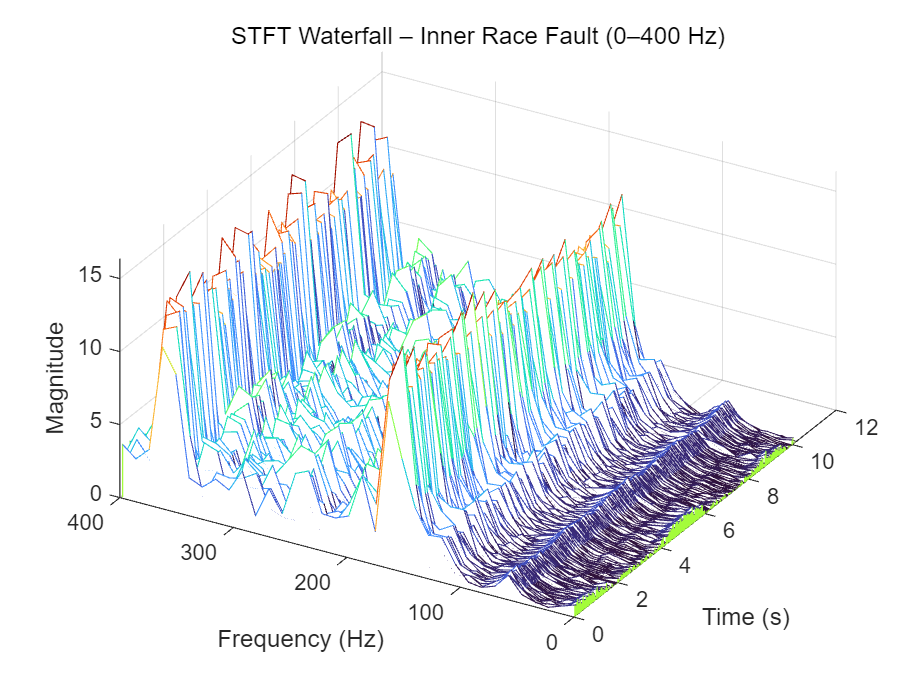

%% ===== STFT Compute =====
x = x_inner_norm;
fs = 12000;

winLen = 1024;
win = hamming(winLen, 'periodic');
overlap = 512;
nfft = 1024;

[S, F, T] = stft(x, fs, ...
    'Window', win, ...
    'OverlapLength', overlap, ...
    'FFTLength', nfft, ...
    'FrequencyRange', 'onesided');

%% ===== Cut frequencies to 0–400 Hz =====
fmax = 400;
idxF = F <= fmax;

F_cut = F(idxF);
S_cut = S(idxF, :);

%% ===== Waterfall Plot =====
figure;
waterfall(F_cut, T, abs(S_cut)');
colormap turbo;
title('STFT Waterfall – Inner Race Fault (0–400 Hz)');
xlabel('Frequency (Hz)');
ylabel('Time (s)');
zlabel('Magnitude');

ax = gca;
ax.XDir = 'reverse';
ax.ZLim = [0 max(abs(S_cut(:)))];
ax.View = [30 45];
grid on;

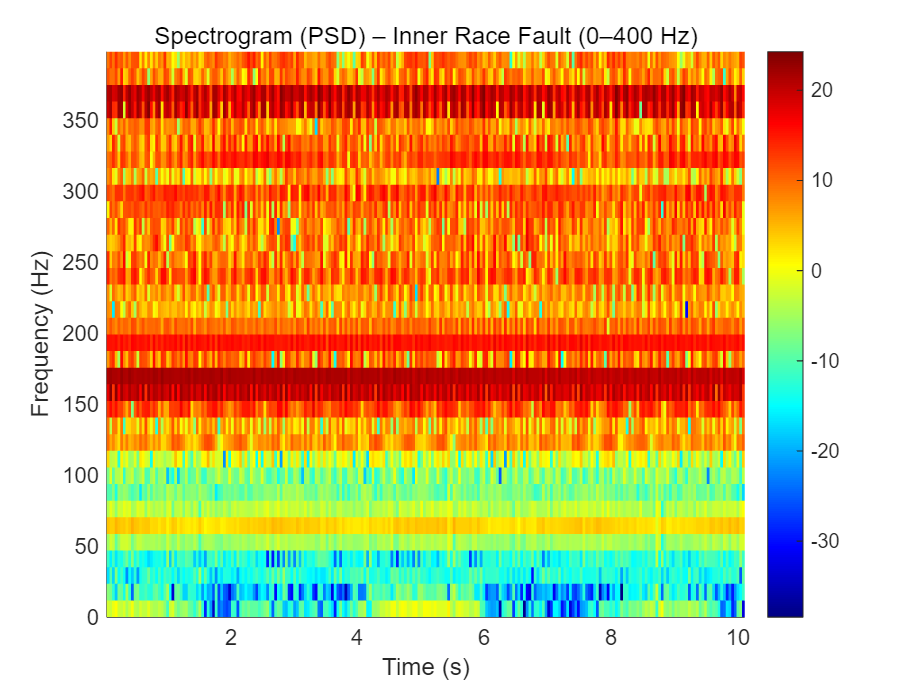

% Compute spectrogram
[Sspec, Fspec, Tspec] = spectrogram(x, win, overlap, nfft, fs);

% === Frequency cut: only keep 0~400 Hz ===
idxF = (Fspec <= 400);
F_cut = Fspec(idxF);
S_cut = Sspec(idxF, :);

% === Plot ===
figure;
surf(Tspec, F_cut, 20*log10(abs(S_cut)), 'EdgeColor', 'none');
axis tight;
view(0, 90);
colormap jet;
colorbar;

title('Spectrogram (PSD) – Inner Race Fault (0–400 Hz)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

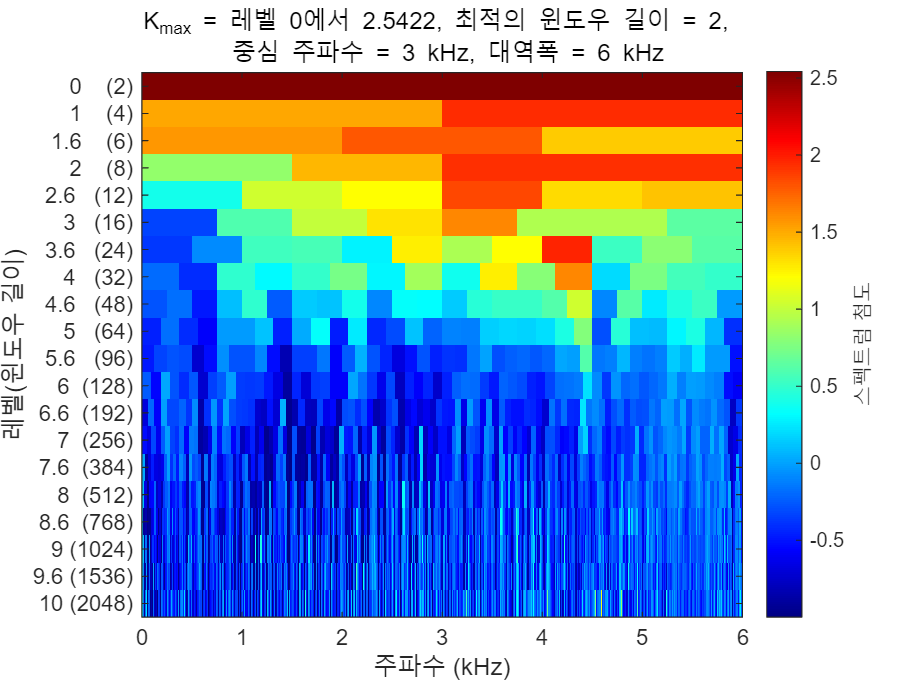

%%% YOUR CODE GOES HERE
kurtogram(x_inner_norm,fs)

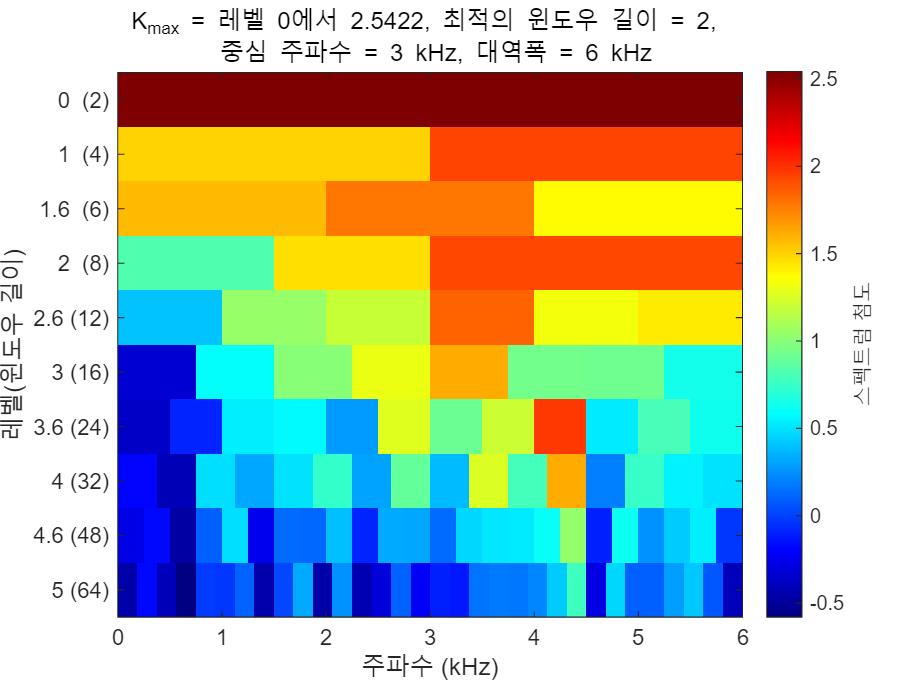

%%% YOUR CODE GOES HERE
level = 5;
kurtogram(x_inner_norm,fs, level)

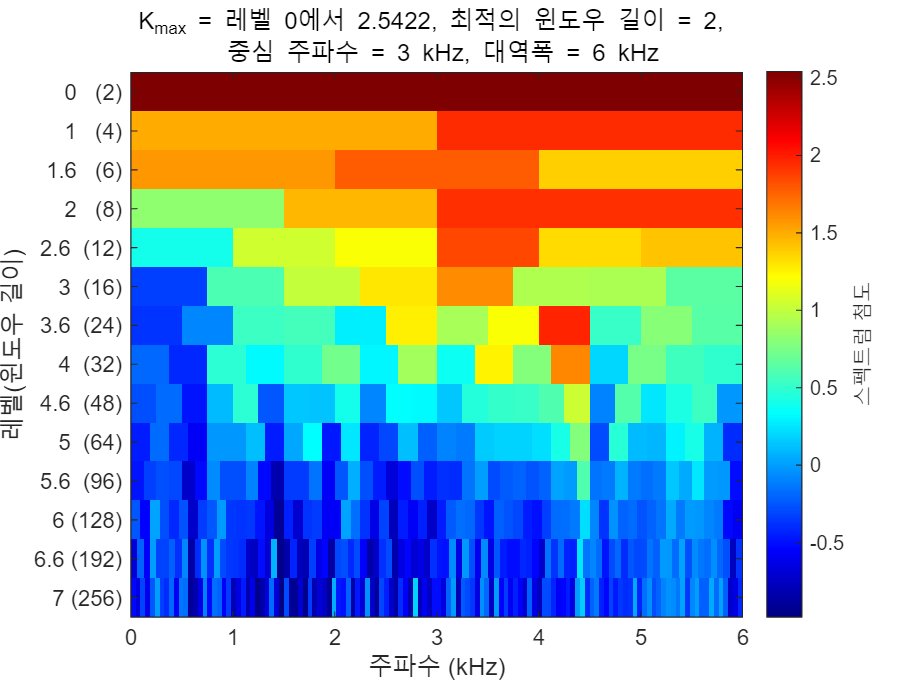

%%% YOUR CODE GOES HERE
level = 7;
kurtogram(x_inner_norm,fs, level)

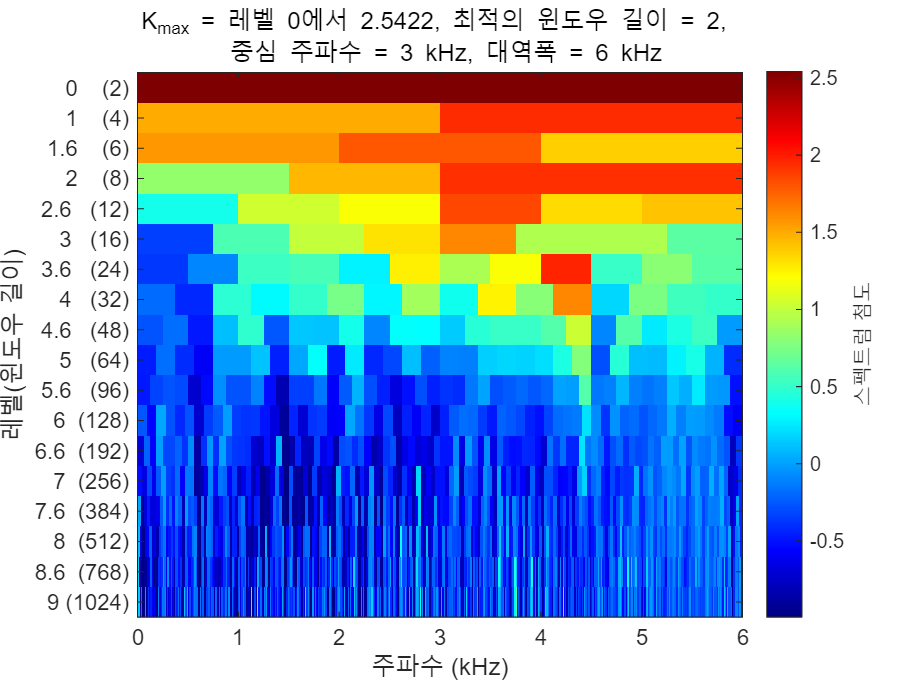

%%% YOUR CODE GOES HERE
level = 9;
kurtogram(x_inner_norm, fs, level)

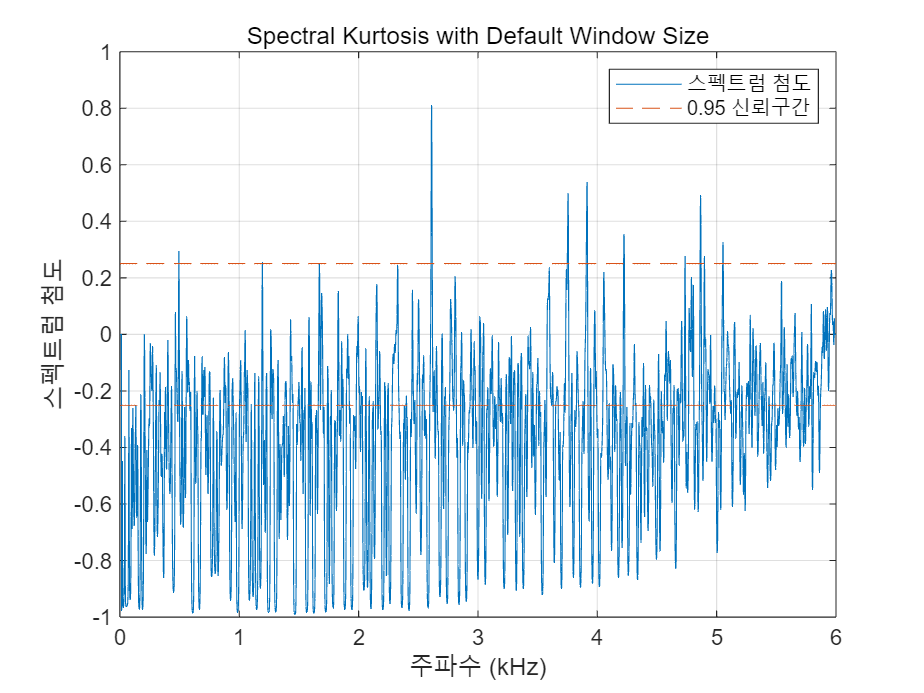

%%% spectral kurtosis
% YOUR CODE GOES HERE
pkurtosis(x_inner,fs)    % your code goes here

title('Spectral Kurtosis with Default Window Size')

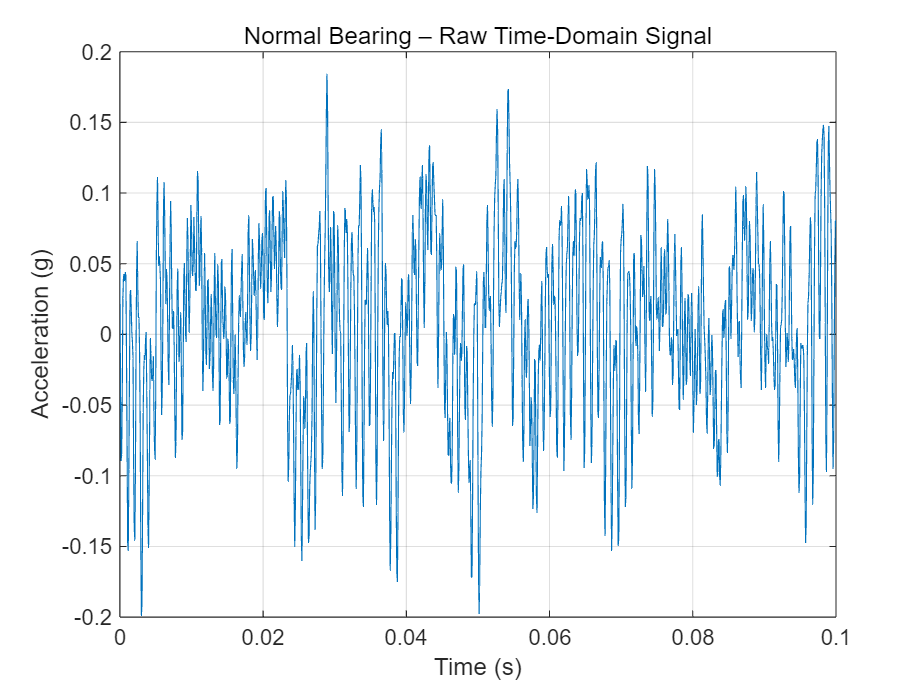


t_normal = (0:length(x_normal)-1)/fs;
%% ================================
% STEP 1 — Time-Domain (Normal)
%% ================================

figure;
plot(t_normal, x_normal);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Normal Bearing – Raw Time-Domain Signal');
xlim([0 0.1]);
grid on;

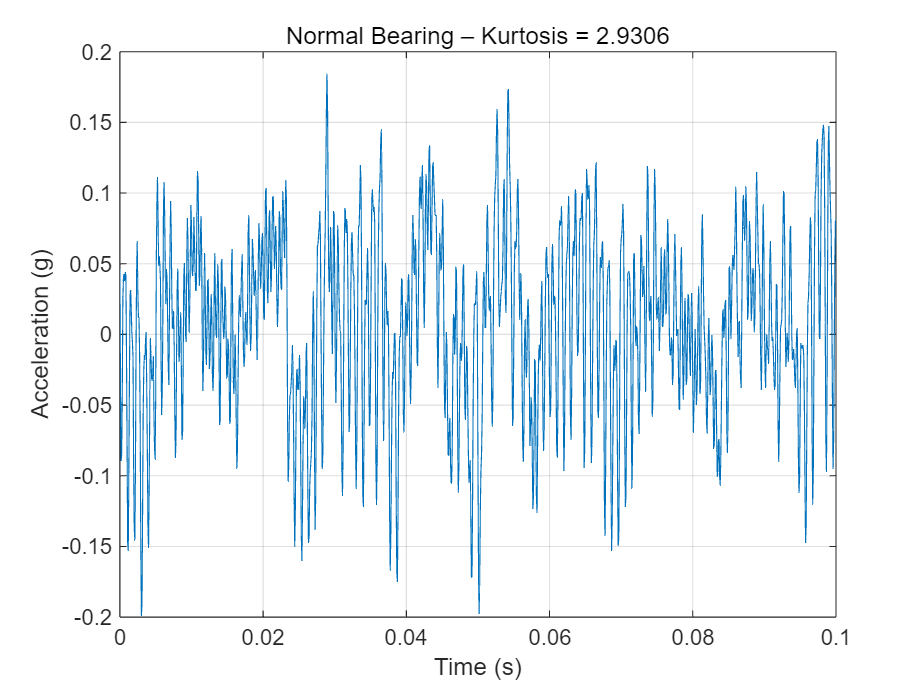

%% ================================
% STEP 2 — Kurtosis (Normal)
%% ================================

% Kurtosis 계산
kurt_normal = kurtosis(x_normal);

% Plot
figure;
plot(t_normal, x_normal);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title(['Normal Bearing – Kurtosis = ' num2str(kurt_normal,'%.4f')]);
xlim([0 0.1]);
grid on;

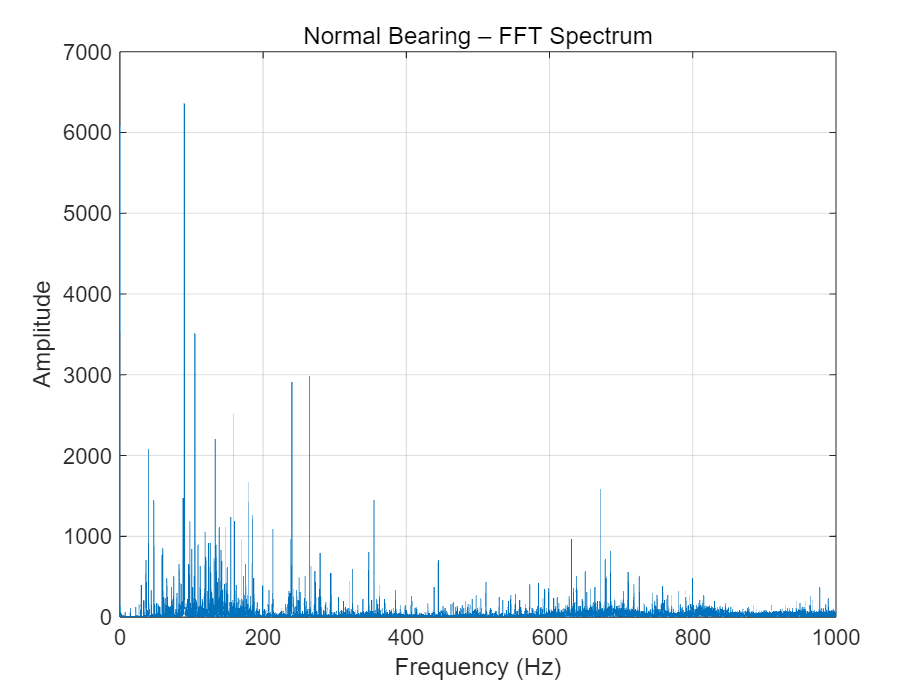

%% ================================
% STEP 3 — FFT (Normal)
%% ================================

% 샘플 길이
L_normal = length(x_normal);

% 주파수 벡터
f_normal = (0:L_normal/2-1) * (fs / L_normal);

% FFT 계산
X_normal = abs(fft(x_normal));
X_normal = X_normal(1:floor(L_normal/2));

% Plot
figure;
plot(f_normal, X_normal);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Normal Bearing – FFT Spectrum');
xlim([0 1000]);   % BPFO/BPFI 보기 위해 0~1000Hz로 제한
grid on;

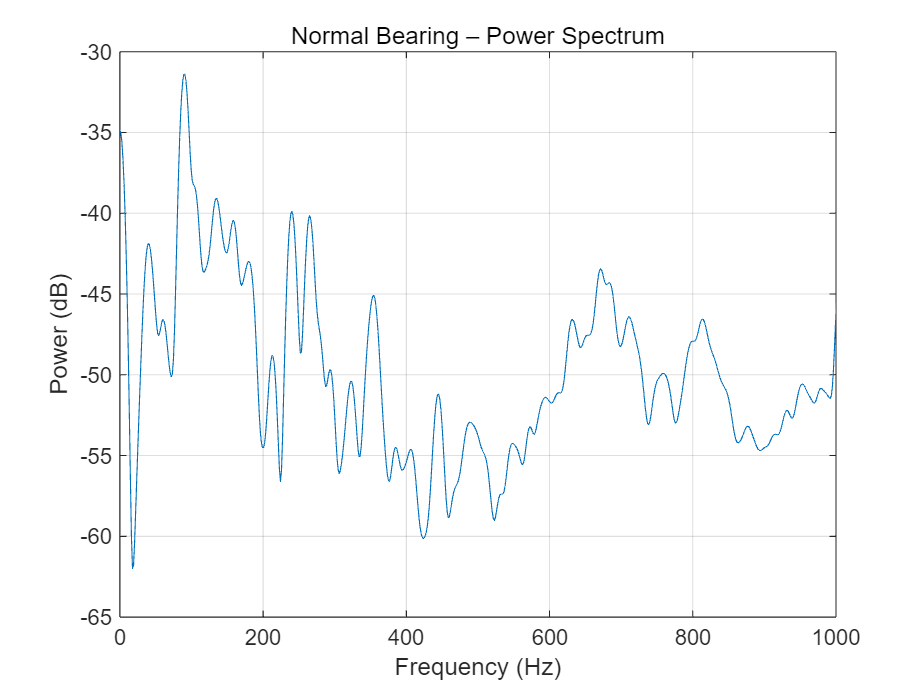

%% ================================
% STEP 4 — Power Spectrum (Normal)
%% ================================

% Power Spectrum 계산
[pNormal, fNormal] = pspectrum(x_normal, fs);

% dB scale 변환
pNormal_dB = 10 * log10(pNormal);

% Plot
figure;
plot(fNormal, pNormal_dB);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('Normal Bearing – Power Spectrum');
xlim([0 1000]);     % BPFI/BPFO 용도
grid on;

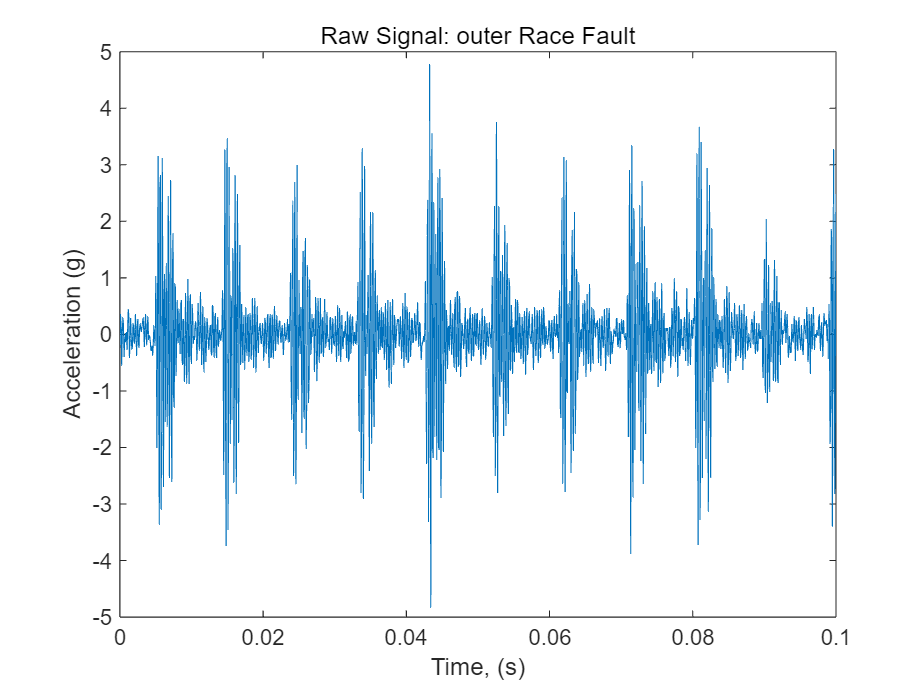

figure
plot(t_outer, x_outer_norm)
xlabel('Time, (s)')
ylabel('Acceleration (g)')
title('Raw Signal: outer Race Fault')
xlim([0 0.1])

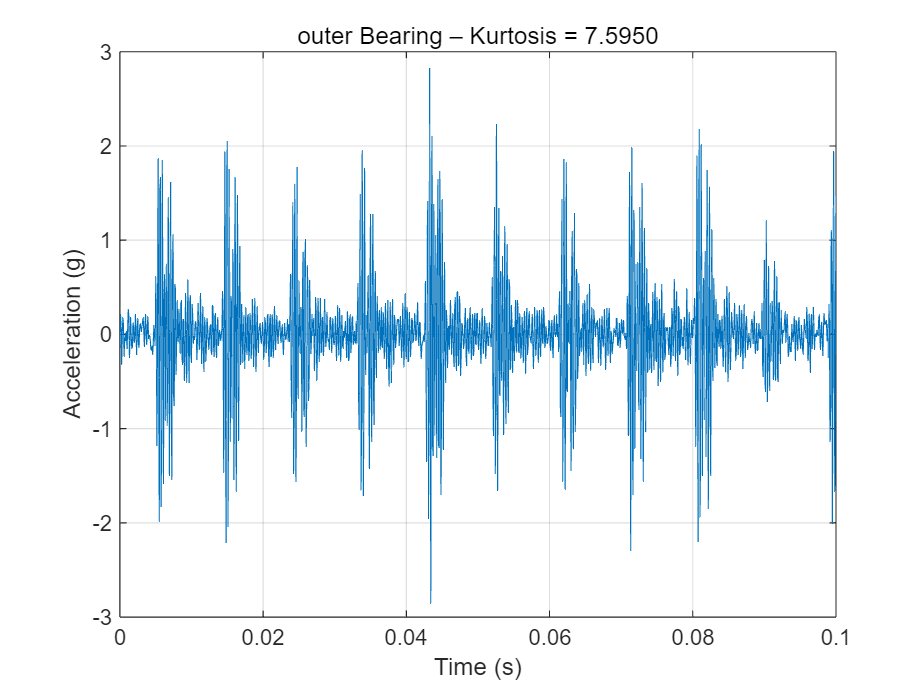

%% ================================
% STEP 2 — Kurtosis (Normal)
%% ================================

% Kurtosis 계산
kurt_outer = kurtosis(x_outer);

% Plot
figure;
plot(t_outer, x_outer);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title(['outer Bearing – Kurtosis = ' num2str(kurt_outer,'%.4f')]);
xlim([0 0.1]);
grid on;


idx = t_outer <= 0.03

idx = 1×122426 logical 배열
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


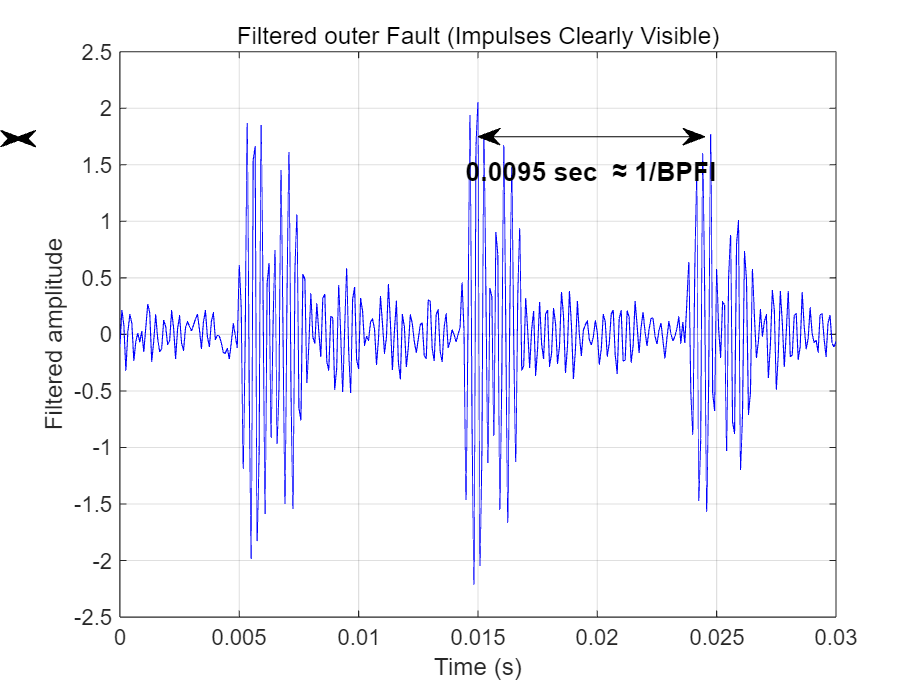


figure;
plot(t_outer(idx), x_outer(idx), 'b');
xlabel('Time (s)');
ylabel('Filtered amplitude');
title('Filtered outer Fault (Impulses Clearly Visible)');
grid on;
hold on;

%% === Mark two impulse peaks manually or automatically ===
% 예: 두 충격 사이 시간 (직접 넘어온 값이거나 자동으로 찾은 값)
t1 = 0.015;  
t2 = 0.0245;

% 화살표 넣기 (양쪽 화살표)
annotation('doublearrow',...
    [t1 t2], [0.8 0.8]);  
% x축 비율을 normalized coords로 바꿔야 하므로 아래 조정 필요

% -----------------------
% 정확한 annotation 위치 계산
% -----------------------
ax = gca;
ax_pos = ax.Position;

x_limits = ax.XLim;
y_limits = ax.YLim;

% normalize to figure coordinates
x1_norm = ax_pos(1) + (t1 - x_limits(1)) / diff(x_limits) * ax_pos(3);
x2_norm = ax_pos(1) + (t2 - x_limits(1)) / diff(x_limits) * ax_pos(3);
y_norm  = ax_pos(2) + 0.85 * ax_pos(4);

annotation('doublearrow', [x1_norm x2_norm], [y_norm y_norm]);

%% === Add text showing delta T ===
T = t2 - t1;
mid = (t1 + t2) / 2;

text(mid, max(x_outer(idx))*0.7, ...
    sprintf('%.4f sec  ≈ 1/BPFI', T), ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 12, 'FontWeight', 'bold');

%% === Outer: Envelope Extraction ===

% 1) Hilbert Transform
analytic_outer = hilbert(x_outer);      % ★ outer 전용 변수
env_outer      = abs(analytic_outer);        % ★ env → env_outer

% 2) Envelope FFT
ENV_FFT_outer = abs(fft(env_outer));         % ★ ENV_FFT → ENV_FFT_outer
L_outer        = length(env_outer);          % ★ L → L_outer
f_outer        = (0:L_outer-1)*(fs/L_outer); % ★ f → f_outer


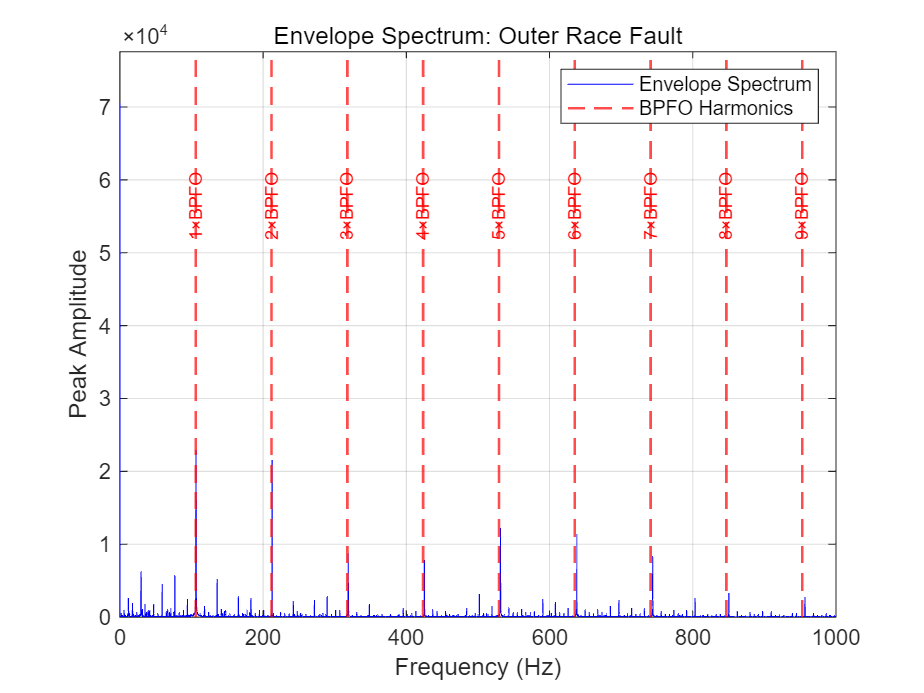

%% === 1. Envelope Spectrum 준비 (Outer) ===
halfL_outer = floor(L_outer/2);

figure;
plot(f_outer(1:halfL_outer), ENV_FFT_outer(1:halfL_outer), 'b'); hold on;
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Outer Race Fault');
ylim([0 max(ENV_FFT_outer(1:halfL_outer))*1.1]);
grid on;


%% === 2. BPFO Harmonics 표시 ===
ncomb = 10;                % 표시할 고조파 개수
fundamental = BPFO;  % ★ Outer fault BPFO 사용

for k = 1:ncomb
    harmonic_freq = k * fundamental;

    if harmonic_freq < 1000
        xline(harmonic_freq,'r--','LineWidth',1.2);
        text(harmonic_freq, max(ENV_FFT_outer(1:halfL_outer))*0.8, ...
            sprintf('%d×BPFO', k), ...   % ★ label 변경됨
            'HorizontalAlignment','center',...
            'Rotation',90, 'FontSize',8, 'Color','r');
    end
end

legend('Envelope Spectrum','BPFO Harmonics');

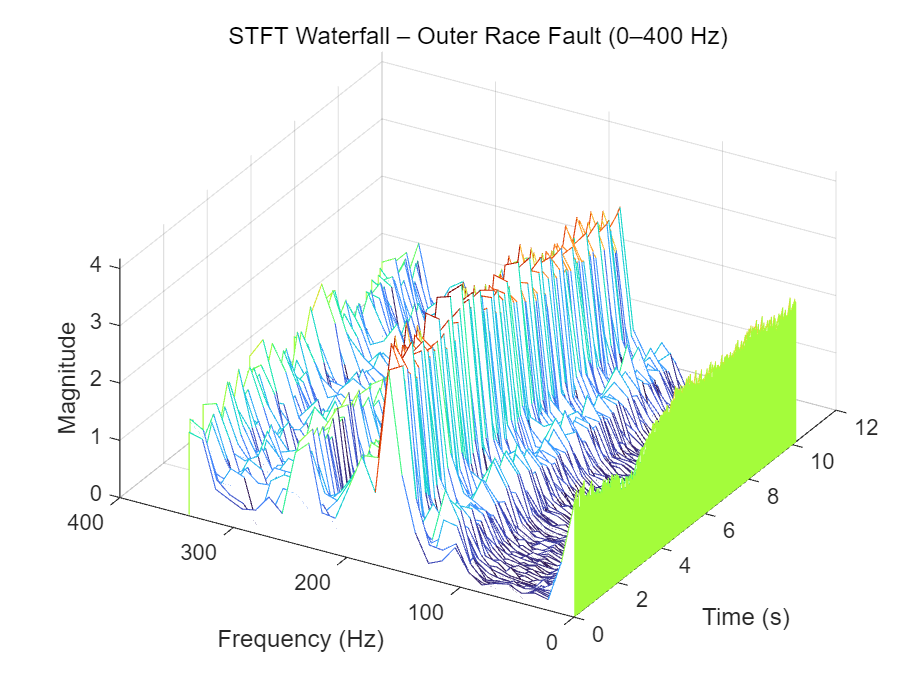

%% === STFT Waterfall – Outer Race Fault ===

% Parameters
winLen = 1024;
win = hamming(winLen, 'periodic');
overlap = 512;
nfft = 1024;

% Compute STFT
[S_out, F_out, T_out] = stft(x_outer, fs, ...
    'Window', win, ...
    'OverlapLength', overlap, ...
    'FFTLength', nfft, ...
    'FrequencyRange', 'onesided');

% ===== 0~400Hz로 잘라내기 =====
idxF_out = F_out <= 350;
F_cut_out = F_out(idxF_out);
S_cut_out = S_out(idxF_out, :);

% ===== Waterfall Plot =====
figure;
waterfall(F_cut_out, T_out, abs(S_cut_out)');
colormap turbo;
title('STFT Waterfall – Outer Race Fault (0–400 Hz)');
xlabel('Frequency (Hz)');
ylabel('Time (s)');
zlabel('Magnitude');

% Formatting (helperGraphicsOpt style)
ax = gca;
ax.XDir = 'reverse';
ax.View = [30 45];
ax.ZLim = [0 max(abs(S_cut_out(:)))];
grid on;

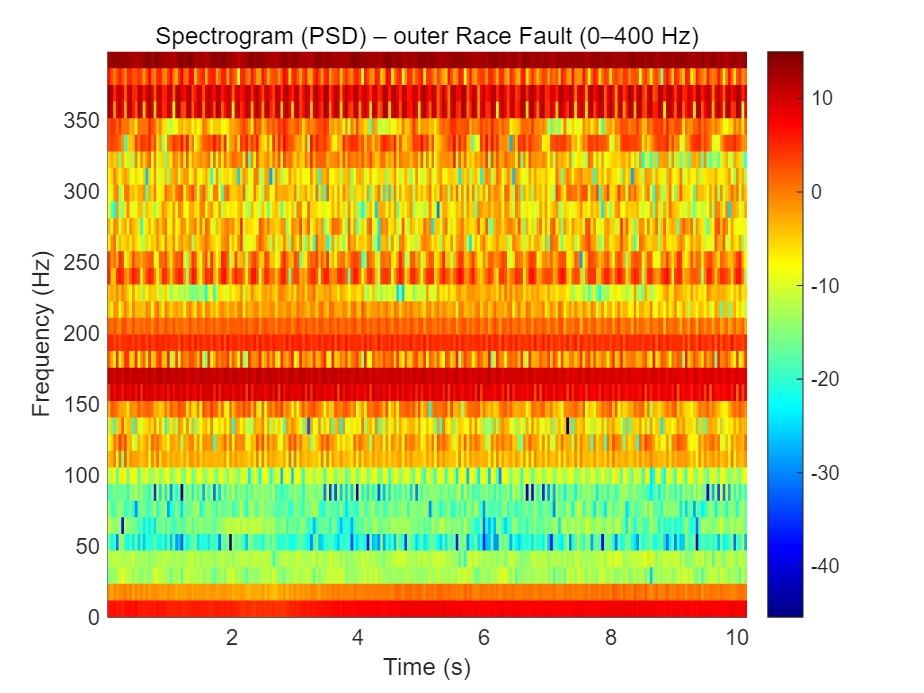

% Compute spectrogram
[Sspec, Fspec, Tspec] = spectrogram(x_outer, win, overlap, nfft, fs);

% === Frequency cut: only keep 0~400 Hz ===
idxF = (Fspec <= 400);
F_cut = Fspec(idxF);
S_cut = Sspec(idxF, :);

% === Plot ===
figure;
surf(Tspec, F_cut, 20*log10(abs(S_cut)), 'EdgeColor', 'none');
axis tight;
view(0, 90);
colormap jet;
colorbar;

title('Spectrogram (PSD) – outer Race Fault (0–400 Hz)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

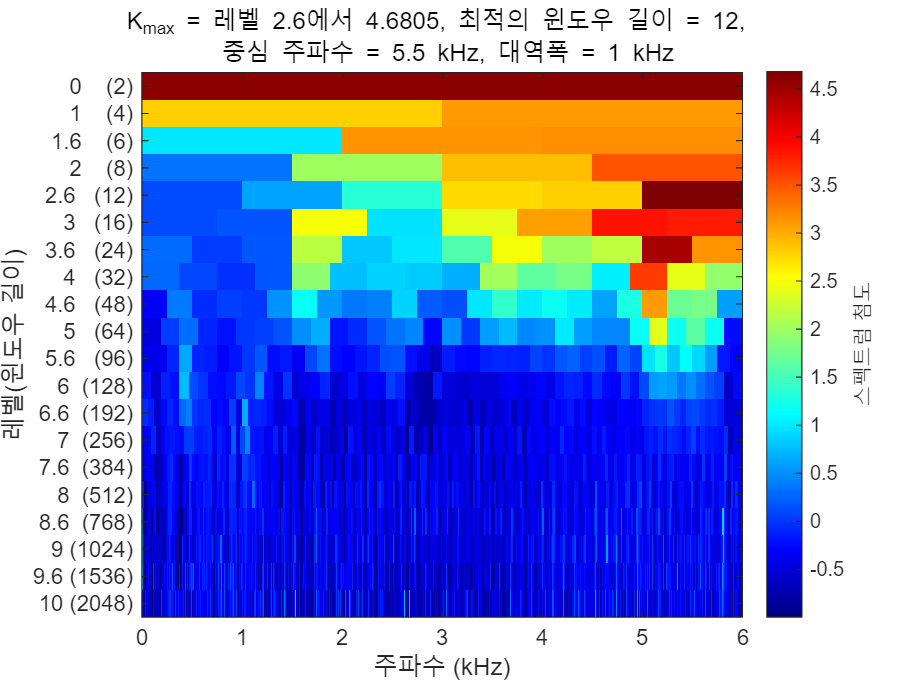

%%% YOUR CODE GOES HERE
kurtogram(x_outer_norm,fs)

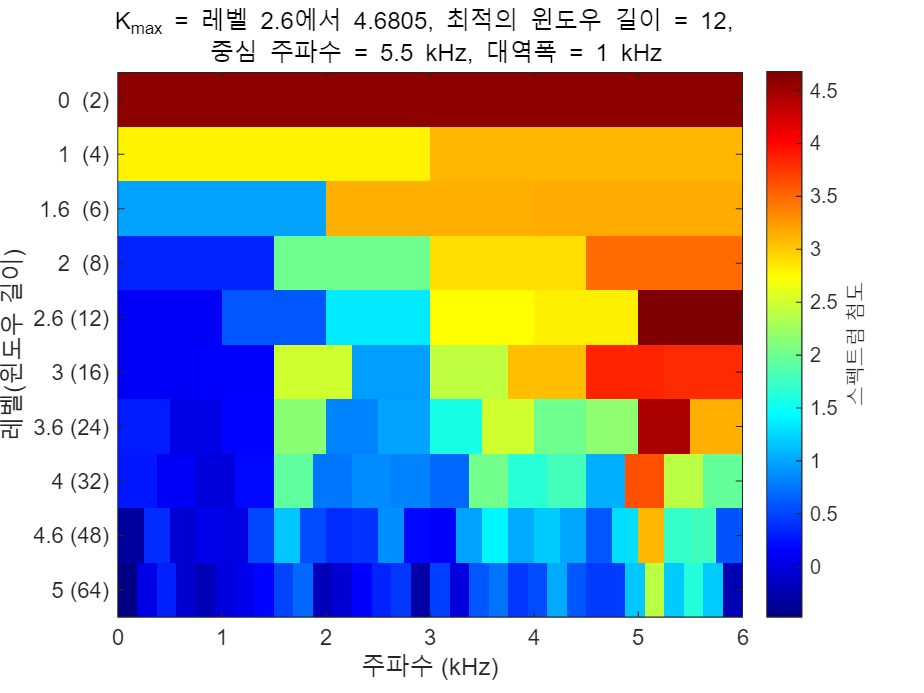

%%% YOUR CODE GOES HERE
level = 5;
kurtogram(x_outer_norm,fs, level)

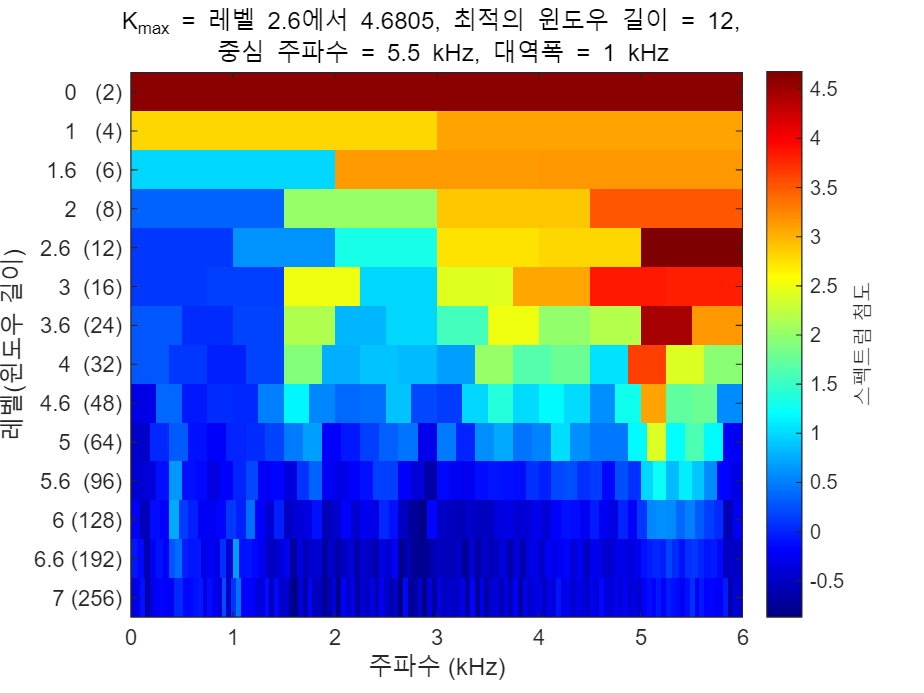

%%% YOUR CODE GOES HERE
level = 7;
kurtogram(x_outer_norm,fs, level)

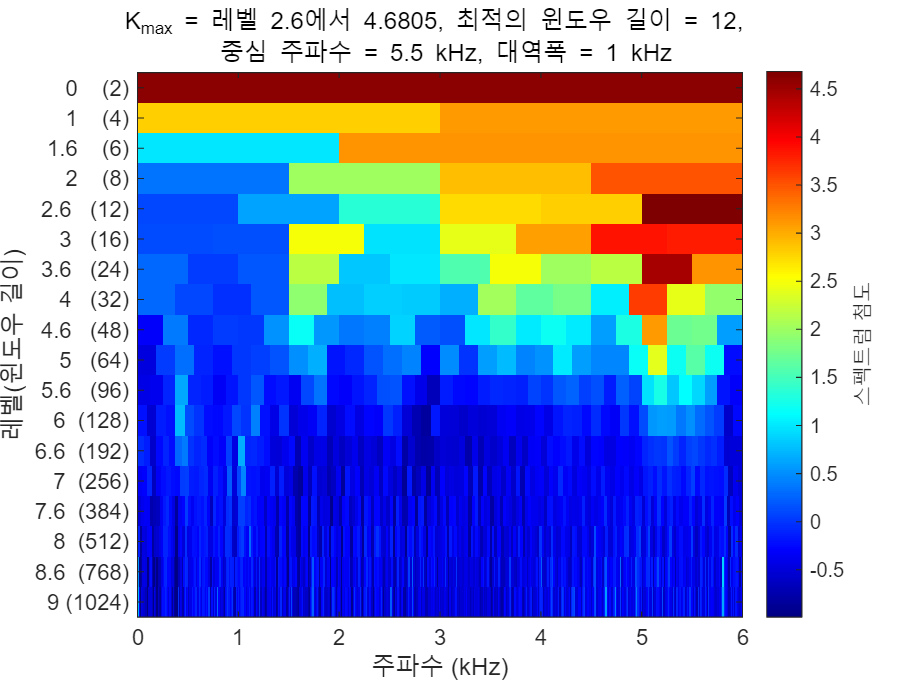

%%% YOUR CODE GOES HERE
level = 9;
kurtogram(x_outer_norm, fs, level)

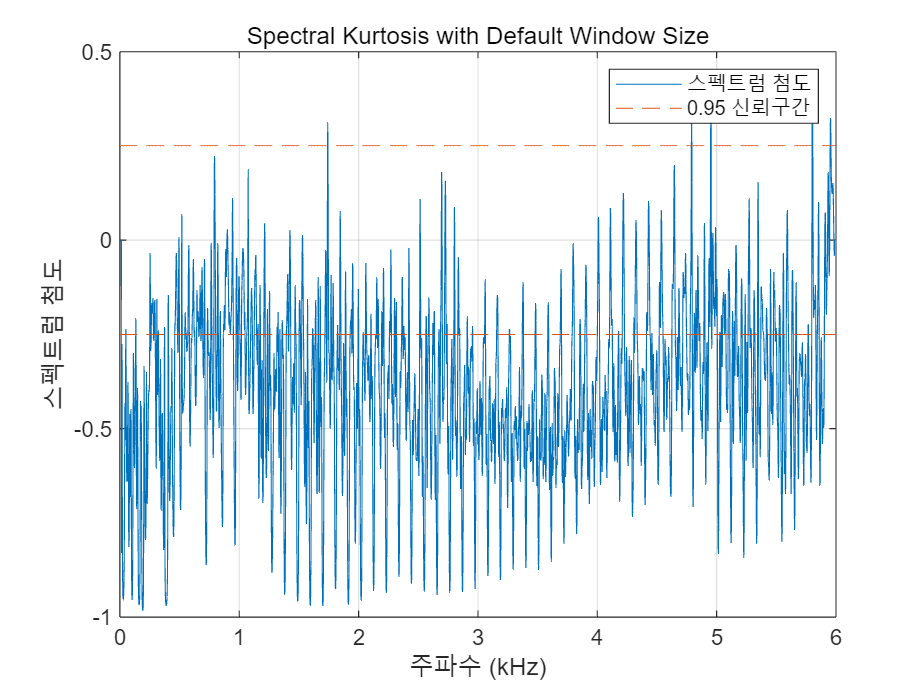

%%% spectral kurtosis
% YOUR CODE GOES HERE
pkurtosis(x_outer,fs)    % your code goes here

title('Spectral Kurtosis with Default Window Size')

## **Feature Analysis and Comparison  **

Compare features among different classes

**A. Inner fault**

**1. Time-Domain Feature Analysis**

Comparing the time-domain characteristics of the inner race fault signal with those of the Normal and Outer classes, the inner signal clearly exhibited several impulsive characteristics. In particular, the kurtosis value increased from 2.93 in the Normal class to 5.54 in the Inner class, indicating the presence of a strong impulsive distribution within the signal. Impulsive shocks occur when the rolling element repeatedly strikes the fault surface. This shock thickens the tails of the signal distribution, significantly increasing kurtosis.Skewness also increased from -0.17 in the Normal class to 0.13 in the Inner class, confirming that the signal distribution is asymmetric rather than symmetric. The Impulse Factor and Margin Factor also increased significantly compared to the Normal class (ImpulseFactor: 6.91 → 7.58, MarginFactor: 8.14 → 9.54). This indicates that the inner fault signal frequently exhibits momentary peaks and persistent impulsive phenomena that are clearly distinct from normal signals. Overall, the time-domain characteristics strongly support the notion that inner race faults are characterized by repetitive impulsive shocks.

**2. Frequency-Domain Feature Analysis**

The characteristics of the inner signal are also revealed in frequency-domain feature analysis (featF). After normalization, the spectral energy is lower than that of the normal signal, but this is because the impulsive shock is distributed broadly. The inner fault instantaneously covers a wide frequency band when the shock occurs, resulting in an evenly distributed spectral density that is not strongly concentrated in a specific region. Furthermore, spectral kurtosis-based feature values, such as **SKMean, SKStd, SKSkewness, and SKKurtosis, showed lower values** for the inner fault than for the normal fault.

This phenomenon is related to the low-frequency repetitive impulse **(BPFI)** characteristics of the inner race fault. While the inner race fault does exhibit impulsiveness, it does not amplify it strongly in the high-frequency band, and therefore, it may not be significantly reflected in the spectral kurtosis measurements.

**3. Fault Characteristic Frequency (BPFI = 159.553 Hz)**

Based on the structural characteristics of the CWRU bearing, the inherent repetition frequency (BPFI) of the inner race fault is **calculated to be 159.553 Hz.**

This is equivalent to the rate at which the rolling element passes the fault approximately **159 times per second.** Time-domain analysis confirmed that the shock bursts repeated at intervals of a**pproximately 0.00627 seconds (= 1/159.553)**, which corresponds to this value. The envelope spectrum revealed a very distinct peak at 159 Hz and its harmonics (ex: 318 Hz, 477 Hz), which is the most conclusive evidence of an inner race fault.

**4. Why Spectral Kurtosis Does Not Strongly Highlight Inner Faults**

For inner race faults, the inherent fault frequency (BPFI) is clearly observed in the envelope spectrum, but is relatively weakly expressed in the spectral kurtosis (SK) or kurtogram. This is a normal phenomenon due to differences in analysis objectives.

Envelope Spectrum:

Optimized for detecting the frequency of repetitive impacts (BPFI) → 159.553 Hz and the harmonic peak are very clear.

Spectral Kurtosis (pkurtosis):

A technique that emphasizes high-frequency impulsive components (broadband spikes at the moment of impact) → Unrelated to the repetitive frequency (BPFI) → Low-frequency repetitive signals are not significantly highlighted in the kurtogram.

Inner race faults have relatively weaker high-frequency impulsive components than outer race faults. The impact generated from the rotating part is not transmitted uniformly to the sensor, resulting in a dispersed impulsiveness. Therefore, the absence of a strong peak in SK is a normal pattern for inner race faults.

**B. Outer fault**

**1. Time-Domain Feature Analysis**

The time-domain characteristics of the Outer race fault signal, compared to the Normal and Inner races, exhibit the strongest impulsive pattern. In particular, the **Kurtosis value was 7.595**, the highest among the three classes. This indicates that the signal distribution is very heavy-tailed, and that it contains repetitive strong impulses. The **skewness also increased from -0.17 for the Normal race to +0.033** for the Outer race, confirming the presence of asymmetrical impulses in the signal.

Furthermore, the **Impulse Factor (8.48) and Margin Factor (11.67) recorded the highest values** among the three classes.

This is due to the characteristics of the stationary fault structure, where the Outer race fault transmits impulses directly toward the sensor, and indicates that the impulses are **strongly input whenever the rolling element contacts the fault.**

**2. Frequency-Domain Feature Analysis**

The characteristics of the outer fault are also confirmed in the frequency-domain feature (featF). When an impulsive shock occurs, the outer fault tends to disperse broadband energy across a wide band, resulting in a total spectral **energy level similar to that of the inner fault (≈ 1.22e5).**

Spectral Kurtosis-related features **(SKMean, SKStd, etc.) showed lower values** than the normal value.

This is interpreted as a result of the **characteristic of high-frequency bursts spreading across a wide frequency band at each impact moment**, rather than the impulsive energy being concentrated in a specific high-frequency band.

In other words, the outer race fault is characterized by **strong broadband impulsiveness** rather than a pattern concentrated in a specific high-frequency region, and this characteristic is reflected in the frequency-domain feature.

**3. Fault Characteristic Frequency (BPFO = 106.252 Hz)**

The characteristic fault frequency (BPFO) of the outer race fault is calculated as follows:

**BPFO = 106.252 Hz**

This means that the rolling element passes the outer race fault approximately 106.252 times per second. Time domain analysis revealed that impulsive bursts were repeated at intervals of **approximately 0.0094 seconds (= 1/106.252)**, which is consistent with this value. This is a key characteristic of an outer race fault. In the envelope spectrum, BPFO and its harmonics are very strong, and are used as the strongest evidence for diagnosing an outer race fault.

In particular, the outer fault in the envelope exhibited a larger harmonic peak than the inner fault. This is because the outer ring is a stationary part, and the fault shock is transmitted directly to the sensor.

**4. Spectral Kurtosis (SK) Analysis**

While the outer race fault exhibited a clearly visible repetitive impulse based on the BPFO (106.252 Hz) in the envelope spectrum, the strong peaks were relatively weak in the spectral kurtosis analysis. This is because the **SK technique does not detect the low-frequency repetitive frequency (BPFO) itself, but rather emphasizes only the high-frequency impulsiveness that occurs at the moment of impact.**

Although the outer fault impulse has a large amplitude, it is not a very sharp (spiky) high-frequency impulse, but rather a broadband impulsiveness that spreads evenly across a wide band. Therefore, the absence of a strong peak at a specific frequency in the SK analysis is a normal pattern.

5. Time-Frequency (STFT) Analysis

In the STFT analysis, only a broadband burst was observed at each impact moment, and the repetitive frequency (≈106 Hz) similar to that of the BPFO was not directly observed. This is because the STFT is a tool for visualizing the onset time of the shock and the broadband energy distribution. **The window resolution (1024 samples) is not sufficiently fine to clearly represent the low-frequency repetition rate** (BPFO) on the frequency axis.

Therefore, while BPFO is clearly visible in the envelope spectrum, it normally appears only as a periodic burst pattern in the STFT.